# Lesson 5

This lesson we will be working with the National Health and Nutrition Examination Survey dataset [Ref [1](https://www.cdc.gov/nchs/nhanes/index.htm), [2](https://learning.rc.virginia.edu/notes/matlab-data-visualization/)].

#### Task 1. Import the data using `readtable` (or `readmatrix`) and examine the file contents.

filename = 'datafiles/nhanes_matlab.xlsx';
data = readtable(filename)

data = 5000×33 table
     id      visit_num      Gender      Age       Race           Education         MaritalStatus      RelationshipStatus    Insured    Income    Poverty    HomeRooms    HomeOwn          Work         Weight    Height    BMI     Pulse    BPSys    BPDia    Testosterone    HDLChol    TotChol    Diabetes    DiabetesAge    nPregncies    nBabies    SleepHrsNight    PhysActive    PhysActiveDays    AlcoholDay    AlcoholYear    Smoki

#### Task 2. Find rows with missing (important) data. Important basically means several first colunms with basic data on a person.

% Hint: use ismissing with table or isnan with matrix
missing = any(ismissing(data(:,1:7)),2);

#### Task 3. Remove the missing data.

data(missing, :) = [];
% data = data(~missing, :);

#### Task 4. Use `convertvars()` or `categorical()` to convert cathegorical data of your choosing to `cathegorical` type.

data = convertvars(data, {'Gender', 'Race', 'Education', 'MaritalStatus', 'RelationshipStatus'}, 'categorical')

data = 3583×33 table
     id      visit_num    Gender    Age      Race       Education      MaritalStatus    RelationshipStatus    Insured    Income    Poverty    HomeRooms    HomeOwn          Work         Weight    Height    BMI     Pulse    BPSys    BPDia    Testosterone    HDLChol    TotChol    Diabetes    DiabetesAge    nPregncies    nBabies    SleepHrsNight    PhysActive    PhysActiveDays    AlcoholDay    AlcoholYear    SmokingStatus

#### Task 5. Use `mergecats()` to merge some cathegories where it makes sense to simplify the data.

categories(data.Education)

ans = 5×1 cell array
    {'8th Grade'     }
    {'9 - 11th Grade'}
    {'College Grad'  }
    {'High School'   }
    {'Some College'  }


data.Education = mergecats(data.Education, {'8th Grade', '9 - 11th Grade'}, "Some School");

#### Task 6. Create a scatter plot of Height vs Weight. Include labels on both axes and a title for your graph.

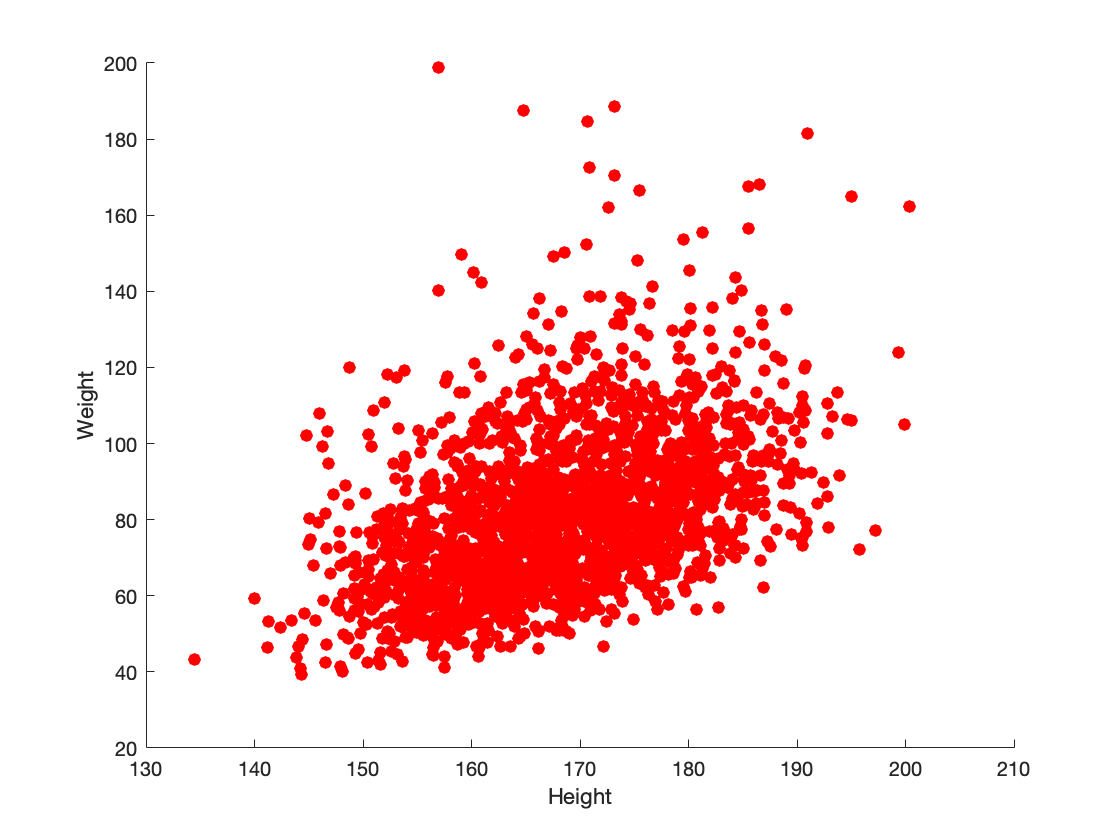

figure
scatter(data.Height, data.Weight, 42, 'red', 'filled', 'o');
xlabel Height
ylabel Weight

#### Task 7. Create overlayed historgram plots showing the proportions of the Highest Level of Education reached at each Income.

categories(data.Education)

ans = 4×1 cell array
    {'Some School' }
    {'College Grad'}
    {'High School' }
    {'Some College'}


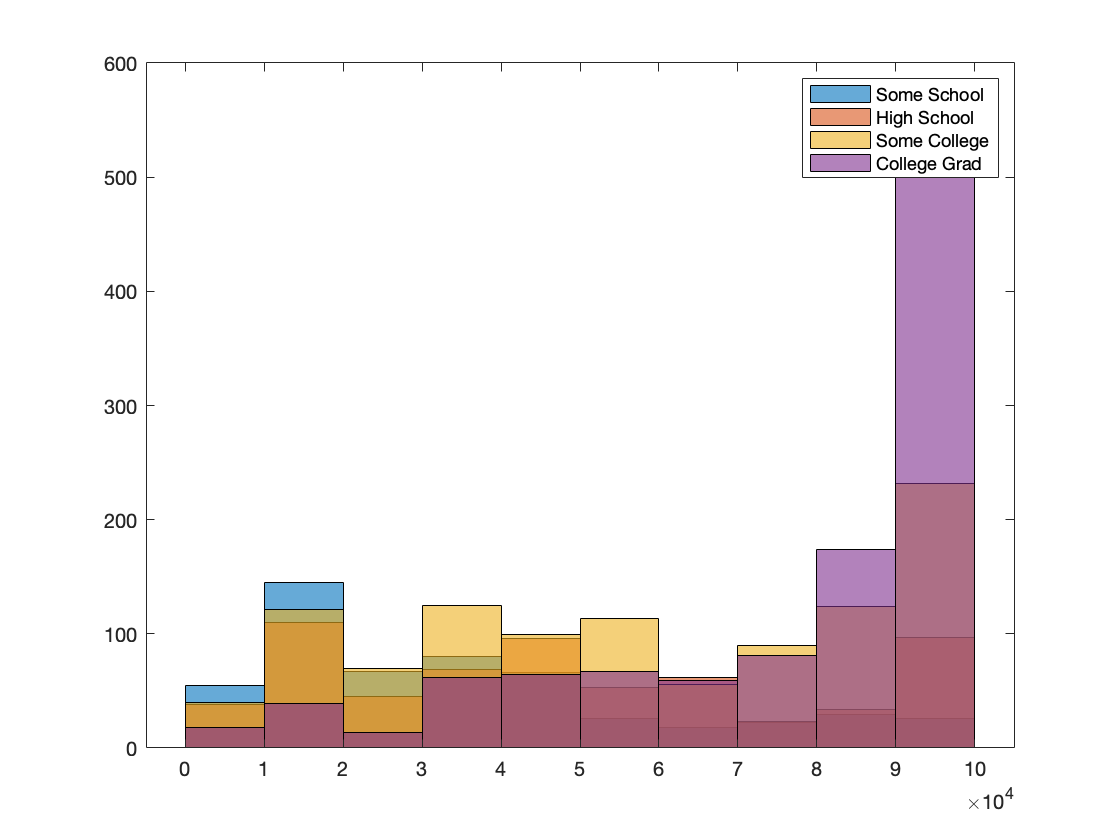

figure
histogram(data.Income(data.Education == 'Some School'))
hold on
histogram(data.Income(data.Education == 'High School'))
histogram(data.Income(data.Education == 'Some College'))
histogram(data.Income(data.Education == 'College Grad'))
legend 'Some School' 'High School' 'Some College' 'College Grad'

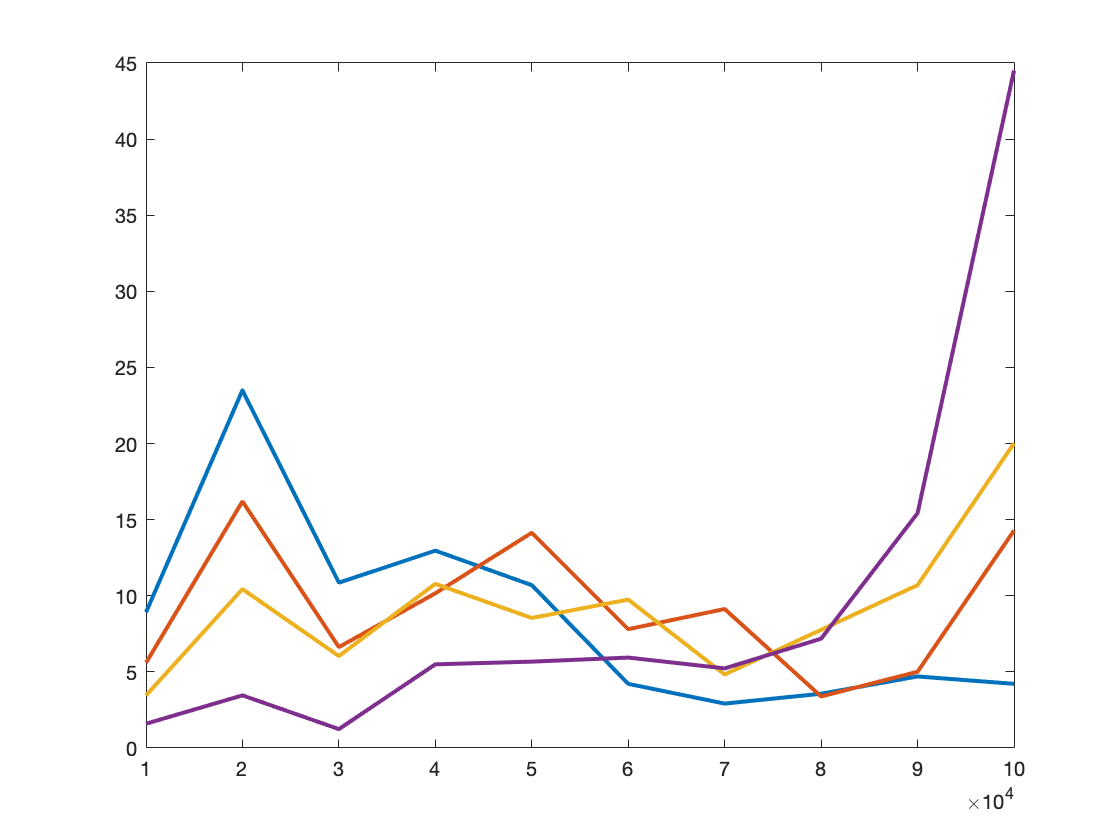


figure
[y,x] = histcounts(data.Income(data.Education == 'Some School'));
plot(x(2:end), y/sum(data.Education == 'Some School')*100, "LineWidth", 2);
hold on
[y,x] = histcounts(data.Income(data.Education == 'High School'));
plot(x(2:end), y/sum(data.Education == 'High School')*100, "LineWidth", 2);
[y,x] = histcounts(data.Income(data.Education == 'Some College'));
plot(x(2:end), y/sum(data.Education == 'Some College')*100, "LineWidth", 2);
[y,x] = histcounts(data.Income(data.Education == 'College Grad'));
plot(x(2:end), y/sum(data.Education == 'College Grad')*100, "LineWidth", 2);

#### Task 8. Create a bar plot of average Cholesterol Level vs Number of Physical Active Days. Include labels on both axes and a title for your graph.

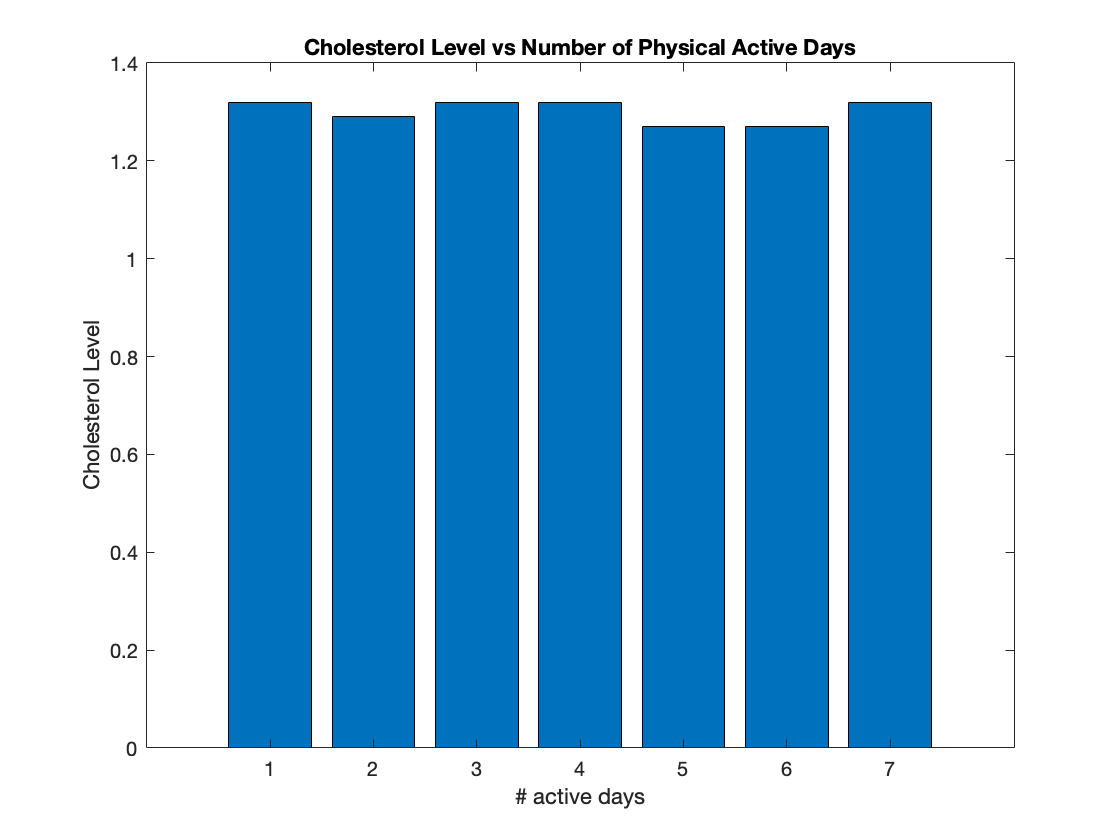

missing = isnan(data.PhysActiveDays) | isnan(data.HDLChol);
days = data.PhysActiveDays(~missing);
chol = data.HDLChol(~missing);
x = unique(days).';
y = zeros(size(x));
for i = 1:length(x)
    y(i) = median(chol(days == x(i)));
end
figure
bar(x, y);
xlabel '# active days'
ylabel 'Cholesterol Level'
title 'Cholesterol Level vs Number of Physical Active Days'